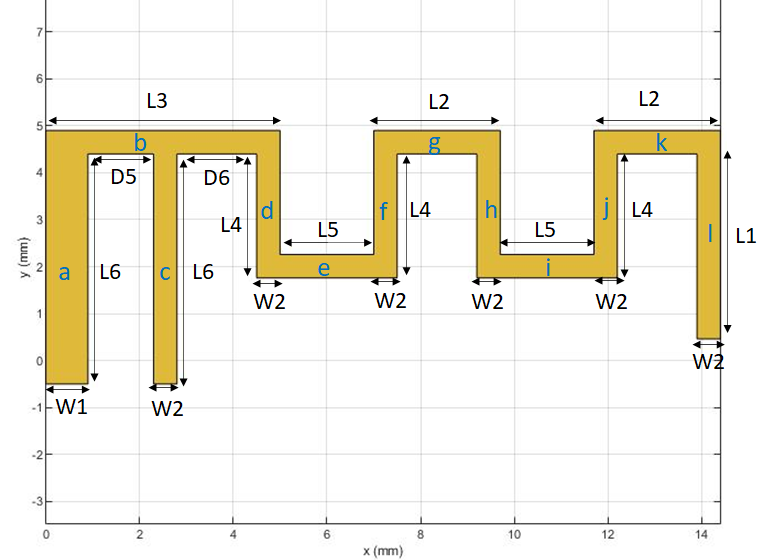

m = 2.54e-5;
W1= 60*m;
W2 = W1;
L6 = 190*m;

L7 = 1e-3;
W3 = W1;
D4 = 0.127e-3;

W4 = W3+D4*2;

D5 = 20*m;
L3 = 790*m;

D1 = 0.5e-3;
D2 = 0.3e-3

D2 = 3.0000e-04

D3 = 0.3e-3

D3 = 3.0000e-04


ED = 4e-4

ED = 4.0000e-04

Lgp = D1+L3+D3; % Length of the Groundplane

Wgp = 75e-3;   % Width of the Groundplane

LBS = Lgp; % Length for the Board Shape
Aheigth = L6+W2+D2

Aheigth = 0.0067

WBS = Wgp+Aheigth;  % Width of the Board Shape
TH = L6+W2/2

TH = 0.0056

ant_gap = 0.7e-3;
edge = 26e-3 - Lgp;
edge_height = Aheigth-D4

edge_height = 0.0065


a = antenna.Rectangle('Length',W1,'Width',L6,'Center',[W1/2,L6/2]);
b = antenna.Rectangle('Length',L3,'Width',W2,'Center',[L3/2,TH]);

c = antenna.Rectangle('Length',W2,'Width',L6,'Center',[W2/2+D5+W1,L6/2]);
d = antenna.Rectangle('Length',W3,'Width',L7,'Center',[W2/2+D5+W1,-L7/2]);

ccut = antenna.Rectangle('Length',W2+2*D4,'Width',L6,'Center',[W2/2+D5+W1,L6/2-D4]);
dcut = antenna.Rectangle('Length',W3+2*D4,'Width',L7+D4,'Center',[W2/2+D5+W1,-L7/2-D4]);

gnd  = antenna.Rectangle('Length',Lgp+edge,'Width',Wgp,'Center',[Lgp/2-edge/2-D1,-Wgp/2]);



gnd = gnd-ccut-dcut

gnd =   Polygon with properties:

        Name: 'mypolygon'
    Vertices: [10×3 double]


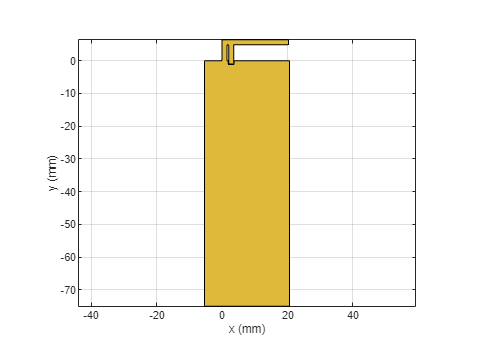


% 
% attach = antenna.Rectangle('Length',W2+ant_gap,'Width',L6+ant_gap,'Center',[W2/2+D5+W1,L6/2-D4]);
% 
% gnd1 = antenna.Rectangle('Length',Lgp+edge,'Width',Wgp,'Center',[Lgp/2-0.5e-3-edge/2,-Wgp/2]);
% cutout = antenna.Rectangle('Length',W2+ant_gap,'Width',L6+ant_gap,'Center',[W2/2+D5+W1,L6/2-D4]);
% 
% gnd1 = gnd1-cutout

Newobj = a+b+c+d+gnd;
figure;
show(Newobj)

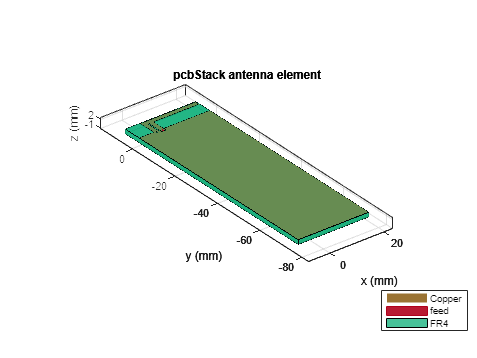


%%
%2 layer Eurocircuits
d = dielectric('FR4');
d.Thickness = 1.55e-3;
d.EpsilonR = 4.5;

%4 layer Eurocircuits
% d = dielectric('FR4');
% d.Thickness = 0.36e-3;
% d.EpsilonR = 4.5;
% d1 = dielectric('FR4');
% d1.Thickness = 0.71e-3+0.36e-3;
% d1.EpsilonR = 4.5;




ant                = pcbStack;
boardshape         = antenna.Rectangle('Length',LBS+edge,'Width',WBS,'Center',[LBS/2-D1-edge/2,Aheigth+(-WBS)/2]);
%cutout             = antenna.Rectangle('Length',edge,'Width',edge_height,'Center',[-edge/2-D1,edge_height/2+D4+D2]);
%boardshape = boardshape-cutout;

ant.BoardShape     = boardshape;
%ant.BoardThickness = d.Thickness+d1.Thickness;
ant.BoardThickness = d.Thickness;%Dual Layer
%gnd                = antenna.Rectangle('Length',Lgp+edge-2*D2,'Width',Wgp+D4-D2,'Center',[Lgp/2-D1-edge/2,D4-Wgp/2]);

gnd                = antenna.Rectangle('Length',Lgp+edge,'Width',Wgp,'Center',[Lgp/2-D1-edge/2,D4-Wgp/2]);

%ant.Layers         = {Newobj,d,gnd,d1};
ant.Layers         = {Newobj,d,gnd};
ant.FeedDiameter   = W2/4;
ant.ViaDiameter    = W1/4;
ant.FeedLocations  = [W1+D5+W2/2,-L7+W2/4,3,1];
ant.ViaLocations   = [W1/2,-W1/4,3,1];
ant.FeedViaModel   = 'square';
ant.Conductor      = metal('Copper');
ant.Conductor.Thickness = 35e-6;
figure;
show(ant);

minf = 2.40e9;
maxf = 2.50e9;
points = 5;
x = 3, y=3

x = 3

y = 3

freqs = linspace(minf,maxf,points)

freqs = 1.0e+09 *

    2.4000    2.4250    2.4500    2.4750    2.5000


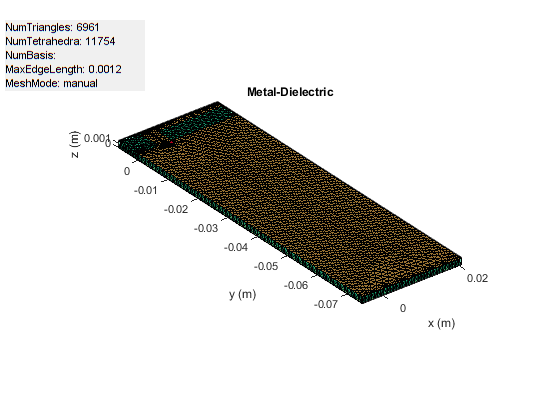

mesh(ant,'MaxEdgeLength', 1.2e-3);

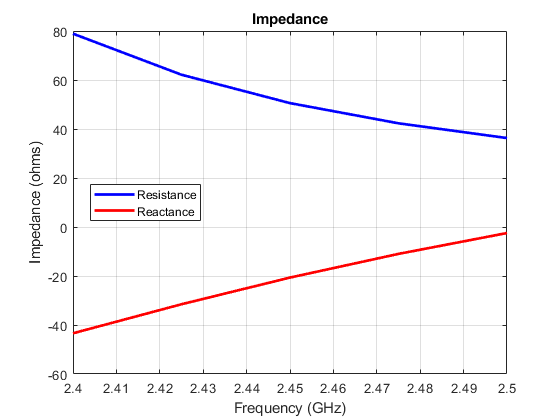

tic
impedance(ant,freqs);

toc

Elapsed time is 905.284676 seconds.


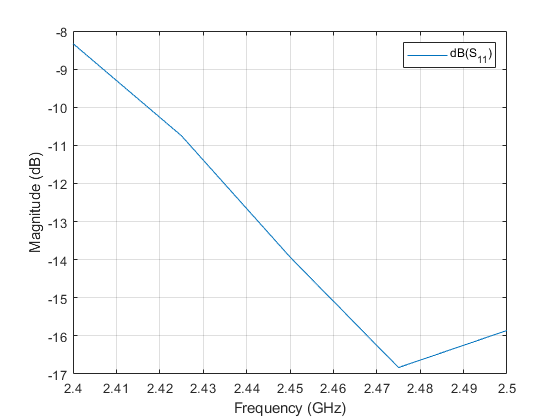

tic
spar = sparameters(ant,freqs);
rfplot(spar)

toc

Elapsed time is 0.767502 seconds.


%profile viewer

%pattern(ant,2.45e9)